addpath Bezier
addpath Simulation\
addpath utils\

PATH_FILEPATH = "path/path.mat"

PATH_FILEPATH = "path/path.mat"

rawPath = load(PATH_FILEPATH)

rawPath = struct with fields:
    xyzquat: [17×7 double]


LASER_EULER_ERROR       = deg2rad([1 -1 1]); 
LASER_TRVEC_ERROR       = [-1 1 1] * 1e-3;    

PART_EULER_ERROR        = deg2rad([2 1 2]);  
PART_TRVEC_ERROR        = [3 1 4] * 1e-3;  

TARGET_BEZIER_OFFSET    = [-1 2 0;1 2 0;2 -1 0; 1 1 0;1 1 0;1 1 0; -1 1 0] * 1e-3;

NUMBER_PATH_POINT     = 17;
LSQ_BEZIER_ALLOW_ERROR  = 1e-3;

midIdx = ceil(NUMBER_PATH_POINT/2);

PART_FILEPATH = "Gripper.stl";
PART_OFFSET = [-0.01, 0, 0.0122];

robot = setupRobot(loadrobot("universalUR3"),PART_FILEPATH, PART_OFFSET);

laserTrvec = [0 0.3 0.3];
laserPose     = se3(laserTrvec,"trvec");

laserOffset   = se3(so3(LASER_EULER_ERROR,"eul"),LASER_TRVEC_ERROR);
partOffset    = se3(so3(PART_EULER_ERROR,"eul"),PART_TRVEC_ERROR);

seamToPart    = se3(rawPath.xyzquat,"xyzquat");

tLerp = linspace(0,1,midIdx);
bz1 = fitBezier(seamToPart(1:midIdx).trvec);
bz2 = fitBezier(seamToPart(midIdx:NUMBER_PATH_POINT).trvec);
tarBz = [bz1(1:3,:);bz2] + TARGET_BEZIER_OFFSET; clear bz1 bz2;

bzCurve1 = getBezier(tarBz(1:4,:),tLerp);
bzCurve2 = getBezier(tarBz(4:end,:),tLerp);

tarPtToPart = [bzCurve1(1:end-1,:);bzCurve2];

ik = inverseKinematics('RigidBodyTree',robot);
weights = [1 1 1 1 1 1];
%initialGuess = robot.randomConfiguration;
load("initialGuess.mat")

jointCommand = [];

partTraj = laserPose*seamToPart.inv;

targetPose = partTraj;
for i  = 1:17

[configSoln,solnInfo] = ik('part',targetPose(i).tform,weights,initialGuess);
jointCommand(i,:) = configSoln;
end

partPlane = genObjPlaneSE3(0.03,0.04);

figure()

i = 5;
config = jointCommand(i,:);

seamPose = partTraj(i)*seamToPart;

partTrajActual = partTraj*partOffset;
laserPoseActual = laserPose*laserOffset;

partTrajActual_i = partTrajActual(i);

devSeamToPart = findIntersectnLinePlane(partTrajActual.inv*laserPoseActual,3,se3([0 0 0],"trvec"),3);
devSeamPose = partTrajActual_i*devSeamToPart;

tarPt = partTrajActual_i.transform(tarPtToPart);

subplot(1,2,1)
h = robot.show(config,"Frames","off");
for jj = 1:8
    h.Children(jj).FaceAlpha = 0.1; % reduce opacity
end
hold on
plotTransforms(laserPoseActual)
plotTraj(seamPose,".-b")

h =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0197 -0.0149 -0.0099 -0.0050 0 0.0050 0.0099 0.0145 0.0187 0.0220 0.0243 0.0259 0.0268 0.0271 0.0271 0.0267 0.0261]
              YData: [0.2992 0.2995 0.2998 0.2999 0.3000 0.2999 0.2997 0.2992 0.2985 0.2975 0.2964 0.2952 0.2939 0.2926 0.2913 0.2900 0.2887]
              ZData: [0.3030 0.3018 0.3009 0.3003 0.3000 0.3003 0.3012 0.3029 0.3057 0.3093 0.3135 0.3181 0.3228 0.3277 0.3325 0.3373 0.3421]

  Show all properties


ans =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0197 -0.0149 -0.0099 -0.0050 0 0.0050 0.0099 0.0145 0.0187 0.0220 0.0243 0.0259 0.0268 0.0271 0.0271 0.0267 0.0261]
              YData: [0.2992 0.2995 0.2998 0.2999 0.3000 0.2999 0.2997 0.2992 0.2985 0.2975 0.2964 0.2952 0.2939 0.2926 0.2913 0.2900 0.2887]
              ZData: [0.3030 0.3018 0.3009 0.3003 0.3000 0.3003 0.3012 0.3029 0.3057 0.3093 0.3135 0.3181 0.3228 0.3277 0.3325 0.3373 0.3421]

  Show all properties


plotTraj(devSeamPose,".-r")

h =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0194 -0.0144 -0.0098 -0.0054 -0.0011 0.0027 0.0059 0.0085 0.0105 0.0121 0.0133 0.0142 0.0147 0.0149 0.0148 0.0145 0.0138]
              YData: [0.3001 0.3004 0.3006 0.3008 0.3008 0.3008 0.3007 0.3005 0.3002 0.2998 0.2993 0.2986 0.2977 0.2967 0.2957 0.2946 0.2933]
              ZData: [0.3098 0.3094 0.3092 0.3092 0.3096 0.3102 0.3112 0.3124 0.3138 0.3156 0.3179 0.3208 0.3242 0.3279 0.3319 0.3361 0.3408]

  Show all properties


ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0194 -0.0144 -0.0098 -0.0054 -0.0011 0.0027 0.0059 0.0085 0.0105 0.0121 0.0133 0.0142 0.0147 0.0149 0.0148 0.0145 0.0138]
              YData: [0.3001 0.3004 0.3006 0.3008 0.3008 0.3008 0.3007 0.3005 0.3002 0.2998 0.2993 0.2986 0.2977 0.2967 0.2957 0.2946 0.2933]
              ZData: [0.3098 0.3094 0.3092 0.3092 0.3096 0.3102 0.3112 0.3124 0.3138 0.3156 0.3179 0.3208 0.3242 0.3279 0.3319 0.3361 0.3408]

  Show all properties


plotTraj(partTrajActual(i)*partPlane,".-")

h =   Line with properties:

              Color: [0.4940 0.1840 0.5560]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0673 0.0056 -0.0325 0.0292 0.0673]
              YData: [0.3029 0.3133 0.3003 0.2899 0.3029]
              ZData: [0.3122 0.2623 0.3068 0.3567 0.3122]

  Show all properties


ans =   Line with properties:

              Color: [0.4940 0.1840 0.5560]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0673 0.0056 -0.0325 0.0292 0.0673]
              YData: [0.3029 0.3133 0.3003 0.2899 0.3029]
              ZData: [0.3122 0.2623 0.3068 0.3567 0.3122]

  Show all properties


plot3(tarPt(:,1),tarPt(:,2),tarPt(:,3),".-k")


hold off
view(180,50)
figScale = 0.1

figScale = 0.1000

xlim([-1 1]*figScale+laserTrvec(1))
ylim([-1 1]*figScale+laserTrvec(2))
zlim([-1 1]*figScale+laserTrvec(3))

subplot(1,2,2)
robot.show(config,"Frames","off")

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


hold on
plotTransforms(laserPose)

plotTraj(seamPose,".-r")

h =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0197 -0.0149 -0.0099 -0.0050 0 0.0050 0.0099 0.0145 0.0187 0.0220 0.0243 0.0259 0.0268 0.0271 0.0271 0.0267 0.0261]
              YData: [0.2992 0.2995 0.2998 0.2999 0.3000 0.2999 0.2997 0.2992 0.2985 0.2975 0.2964 0.2952 0.2939 0.2926 0.2913 0.2900 0.2887]
              ZData: [0.3030 0.3018 0.3009 0.3003 0.3000 0.3003 0.3012 0.3029 0.3057 0.3093 0.3135 0.3181 0.3228 0.3277 0.3325 0.3373 0.3421]

  Show all properties


ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0197 -0.0149 -0.0099 -0.0050 0 0.0050 0.0099 0.0145 0.0187 0.0220 0.0243 0.0259 0.0268 0.0271 0.0271 0.0267 0.0261]
              YData: [0.2992 0.2995 0.2998 0.2999 0.3000 0.2999 0.2997 0.2992 0.2985 0.2975 0.2964 0.2952 0.2939 0.2926 0.2913 0.2900 0.2887]
              ZData: [0.3030 0.3018 0.3009 0.3003 0.3000 0.3003 0.3012 0.3029 0.3057 0.3093 0.3135 0.3181 0.3228 0.3277 0.3325 0.3373 0.3421]

  Show all properties


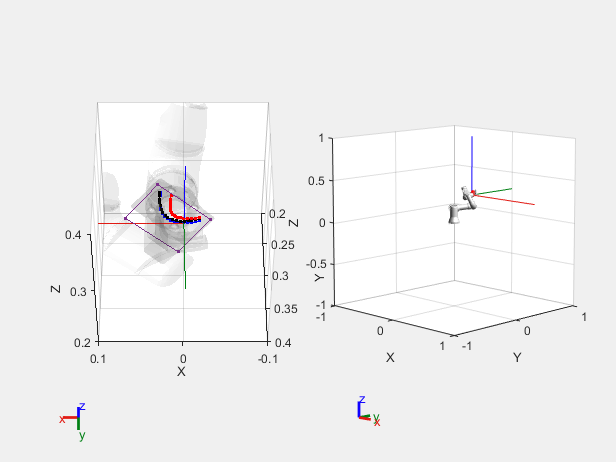

hold off
view(45,10)

devSeamToPart = findIntersectnLinePlane(partTrajActual.inv*laserPoseActual,3,partTrajActual.inv.*partTrajActual,3);

bz1 = fitBezier(seamToPart(1:midIdx).trvec);
bz2 = fitBezier(seamToPart(midIdx:NUMBER_PATH_POINT).trvec);
refBz = [bz1(1:3,:);bz2]; clear bz1 bz2;

bz1 = fitBezier(devSeamToPart(1:midIdx).trvec);
bz2 = fitBezier(devSeamToPart(midIdx:NUMBER_PATH_POINT).trvec);
devBz = [bz1(1:3,:);bz2]; clear bz1 bz2;

adjBz = tarBz + (refBz-devBz);

bzCurve1 = getBezier(adjBz(1:4,:),tLerp);
bzCurve2 = getBezier(adjBz(4:end,:),tLerp);

adjXYZ = [bzCurve1(1:end-1,:);bzCurve2]; clear bzCurve1 bzCurve2
adjSeamXyzquat = [adjXYZ rawPath.xyzquat(:,4:7)];

adjSeamToPart = se3(adjSeamXyzquat,"xyzquat")

adjSeamToPart = 1×17 se3 array
adjSeamToPart(1,1) = 

   -0.8100   -0.1518    0.5664    0.0217
    0.5864   -0.2096    0.7824   -0.0311
         0    0.9659    0.2588    0.0000
         0         0         0    1.0000


adjSeamToPart(1,2) = 

   -0.8100   -0.1518    0.5664    0.0179
    0.5864   -0.2096    0.7824   -0.0291
         0    0.9659    0.2588    0.0000
         0         0         0    1.0000


adjSeamToPart(1,3) = 

   -0.7756   -0.1634    0.6097    0.0137
    0.6312   -0.2007    0.7492   -0.0268
    0.0000    0.9659    0.2588    0.0000
         0         0         0    1.0000


adjSeamToPart(1,4) = 

   -0.7286   -0.1773    0.6616    0.0092
    0.6849   -0.1886    0.7038   -0.0241
    0.0000    0.9659    0.2588    0.0000
         0         0         0    1.0000


adjSeamToPart(1,5) = 

   -0.6623   -0.1939    0.7237    0.0049
    0.7492   -0.1714    0.6398   -0.0208
   -0.0000    0.9659    0.2588    0.0000
         0         0         0    1.0000


adjSeamToPart(1,6) = 

 

figure()
hold on
plotTraj(seamToPart,"-b")

h =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0233 0.0192 0.0152 0.0115 0.0080 0.0049 0.0023 6.1254e-04 0 6.1254e-04 0.0023 0.0049 0.0080 0.0115 0.0152 0.0192 0.0233]
              YData: [-0.0306 -0.0277 -0.0247 -0.0214 -0.0179 -0.0139 -0.0096 -0.0049 0 0.0049 0.0096 0.0139 0.0179 0.0214 0.0247 0.0277 0.0306]
              ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]

  Show all properties


ans =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0233 0.0192 0.0152 0.0115 0.0080 0.0049 0.0023 6.1254e-04 0 6.1254e-04 0.0023 0.0049 0.0080 0.0115 0.0152 0.0192 0.0233]
              YData: [-0.0306 -0.0277 -0.0247 -0.0214 -0.0179 -0.0139 -0.0096 -0.0049 0 0.0049 0.0096 0.0139 0.0179 0.0214 0.0247 0.0277 0.0306]
              ZData: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]

  Show all properties


plotTraj(devSeamToPart,"-r")

h =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0240 0.0204 0.0173 0.0144 0.0120 0.0101 0.0088 0.0080 0.0079 0.0083 0.0093 0.0111 0.0134 0.0163 0.0195 0.0230 0.0273]
              YData: [-0.0280 -0.0245 -0.0211 -0.0176 -0.0142 -0.0108 -0.0077 -0.0049 -0.0025 -1.2891e-04 0.0023 0.0049 0.0076 0.0102 0.0128 0.0152 0.0178]
              ZData: [-7.5894e-18 -6.7221e-18 -6.0715e-18 -4.7705e-18 -3.9031e-18 -3.0358e-18 -1.7347e-18 -8.6736e-19 0 8.6736e-19 2.1684e-18 3.4694e-18 4.7705e-18 6.0715e-18 7.8063e-18 9.5410e-18 1.0842e-17]

  Show <a href="matlab:if exist('h', 'var'), matlab.graphics.internal.getForDisplay('h', h, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('h'), end">all properties</a

ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0240 0.0204 0.0173 0.0144 0.0120 0.0101 0.0088 0.0080 0.0079 0.0083 0.0093 0.0111 0.0134 0.0163 0.0195 0.0230 0.0273]
              YData: [-0.0280 -0.0245 -0.0211 -0.0176 -0.0142 -0.0108 -0.0077 -0.0049 -0.0025 -1.2891e-04 0.0023 0.0049 0.0076 0.0102 0.0128 0.0152 0.0178]
              ZData: [-7.5894e-18 -6.7221e-18 -6.0715e-18 -4.7705e-18 -3.9031e-18 -3.0358e-18 -1.7347e-18 -8.6736e-19 0 8.6736e-19 2.1684e-18 3.4694e-18 4.7705e-18 6.0715e-18 7.8063e-18 9.5410e-18 1.0842e-17]

  Show all pro

plot(tarPtToPart(:,1),tarPtToPart(:,2),"-k")
plotTraj(adjSeamToPart,"-c")

h =   Line with properties:

              Color: [0 1 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0217 0.0179 0.0137 0.0092 0.0049 8.4044e-04 -0.0026 -0.0053 -0.0069 -0.0059 -0.0037 -5.5925e-04 0.0032 0.0072 0.0113 0.0151 0.0184]
              YData: [-0.0311 -0.0291 -0.0268 -0.0241 -0.0208 -0.0166 -0.0113 -0.0047 0.0035 0.0111 0.0179 0.0239 0.0291 0.0337 0.0377 0.0412 0.0443]
              ZData: [7.5894e-18 6.8076e-18 5.9106e-18 4.9321e-18 3.9059e-18 2.8658e-18 1.8456e-18 8.7909e-19 0 -9.5076e-19 -2.0894e-18 -3.3797e-18 -4.7856e-18 -6.2709e-18 -7.7995e-18 -9.3353e-18 -1.0842e-17]

  Show all prope

ans =   Line with properties:

              Color: [0 1 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0217 0.0179 0.0137 0.0092 0.0049 8.4044e-04 -0.0026 -0.0053 -0.0069 -0.0059 -0.0037 -5.5925e-04 0.0032 0.0072 0.0113 0.0151 0.0184]
              YData: [-0.0311 -0.0291 -0.0268 -0.0241 -0.0208 -0.0166 -0.0113 -0.0047 0.0035 0.0111 0.0179 0.0239 0.0291 0.0337 0.0377 0.0412 0.0443]
              ZData: [7.5894e-18 6.8076e-18 5.9106e-18 4.9321e-18 3.9059e-18 2.8658e-18 1.8456e-18 8.7909e-19 0 -9.5076e-19 -2.0894e-18 -3.3797e-18 -4.7856e-18 -6.2709e-18 -7.7995e-18 -9.3353e-18 -1.0842e-17]

  Show 

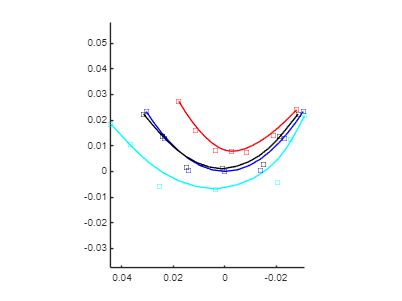

plot(refBz(:,1),refBz(:,2),"sb")
plot(devBz(:,1),devBz(:,2),"sr")
plot(tarBz(:,1),tarBz(:,2),"sk")
plot(adjBz(:,1),adjBz(:,2),"sc")
hold off
view(-90,90)
axis equal

jointCommandCor = [];

partTrajCor = laserPose*adjSeamToPart.inv;

targetPoseCor = partTrajCor;
for i  = 1:17
[configSoln,solnInfo] = ik('part',targetPoseCor(i).tform,weights,initialGuess);
jointCommandCor(end+1,:) = configSoln;
end

writeObj = VideoWriter('testVDO',"MPEG-4");
writeObj.Quality = 100;
open(writeObj)


for i= 1:17

config = jointCommand(i,:);
configCor = jointCommandCor(i,:);

partTrajActual = partTraj*partOffset;
partTrajActualCor = partTrajCor*partOffset;
laserPoseActual = laserPose*laserOffset;

partTrajActual_i = partTrajActualCor(i);
devSeamPose = partTraj(i)*devSeamToPart;

adjSeamPose = partTrajActualCor(i)*adjSeamToPart;

weldSeamToPart = findIntersectnLinePlane(partTrajActualCor.inv*laserPoseActual,3,partTrajActualCor.inv.*partTrajActualCor,3);
weldSeamPose = partTrajActualCor(i)*weldSeamToPart;

tarPt =  partTraj(i).transform(tarPtToPart);
tarPtCor = partTrajActualCor(i).transform(tarPtToPart);

mmm = 2;
nnn = 2;

subplot(mmm,nnn,1)

h = robot.show(config,"Frames","off");
for jj = 1:8
    h.Children(jj).FaceAlpha = 0.1;
end
hold on
plotOrientation(laserPoseActual,3,2,".-r","linewidth",1.5)
hPlotDevSeam = plotTraj(devSeamPose(1:i),"-r","linewidth",2)

plotTraj(partTrajActual(i)*partPlane,"-","linewidth",0.5,"color",[1 1 1]*0.4)
plot3(tarPtCor(:,1),tarPtCor(:,2),tarPtCor(:,3),"-k","linewidth",1)

hPlotTraj = plotTraj(partTraj,"--b","linewidth",1)
hold off
title("Before correction")

figScale = 0.06;
outViewScale = 0.3;
xlim([-1 1]*figScale+laserTrvec(1))
ylim([-1 1]*figScale+laserTrvec(2))
zlim([-1 1]*figScale+laserTrvec(3))

view(190,10)
grid off



subplot(mmm,nnn,2)

h = robot.show(configCor,"Frames","off");
for jj = 1:8
    h.Children(jj).FaceAlpha = 0.1; 
end
hold on
plotOrientation(laserPoseActual,3,2,".-r","linewidth",1.5)
hPlotWeldSeam = plotTraj(weldSeamPose(1:i),"-g","linewidth",2)
plotTraj(partTrajActualCor(i)*partPlane,"-","linewidth",0.5,"color",[1 1 1]*0.4)
hPlotTargetSeam = plot3(tarPtCor(:,1),tarPtCor(:,2),tarPtCor(:,3),"-k","linewidth",1)
hPlotTrajCor = plotTraj(partTrajCor,"--c","linewidth",1)
hold off
title("After Correction")


xlim([-1 1]*figScale+laserTrvec(1))
ylim([-1 1]*figScale+laserTrvec(2))
zlim([-1 1]*figScale+laserTrvec(3))
grid off

view(190,10)
subplot(mmm,nnn,3)

robot.show(config,"Frames","off")
hold on
plotOrientation(laserPoseActual,3,2,".-r","linewidth",1.5)
plotTraj(devSeamPose,".-r")
hold off
xlim([-1 1]*outViewScale+laserTrvec(1))
ylim([-1 1]*outViewScale+laserTrvec(2))
zlim([-1 1]*outViewScale+laserTrvec(3))

subplot(mmm,nnn,4)

robot.show(config,"Frames","off")
hold on
plotOrientation(laserPoseActual,3,2,".-r","linewidth",1.5)
plotTraj(weldSeamPose,".-g")
hold off
xlim([-1 1]*outViewScale+laserTrvec(1))
ylim([-1 1]*outViewScale+laserTrvec(2))
zlim([-1 1]*outViewScale+laserTrvec(3))


Lgnd = legend([hPlotDevSeam hPlotWeldSeam hPlotTargetSeam hPlotTraj hPlotTrajCor],{"Uncorrected seam","Corrected seam","Target seam","Uncorrected Trajectory","Corrected Trajectory"});
Lgnd.Position(1) = 0.85;
Lgnd.Position(2) = 0.45;

F = getframe(gcf);

for kk = 1:10
writeVideo(writeObj,F)
end

end

h =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 9.9861e-04
              YData: 0.2994
              ZData: 0.3023

  Show all properties


hPlotDevSeam =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: 9.9861e-04
              YData: 0.2994
              ZData: 0.3023

  Show all properties


h =   Line with properties:

              Color: [0.4000 0.4000 0.4000]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0832 0.0341 -0.0132 0.0359 0.0832]
              YData: [0.2988 0.3124 0.3019 0.2882 0.2988]
              ZData: [0.3274 0.2657 0.3010 0.3627 0.3274]

  Show all properties


ans =   Line with properties:

              Color: [0.4000 0.4000 0.4000]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0832 0.0341 -0.0132 0.0359 0.0832]
              YData: [0.2988 0.3124 0.3019 0.2882 0.2988]
              ZData: [0.3274 0.2657 0.3010 0.3627 0.3274]

  Show all properties


h =   Line with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0368 0.0318 0.0274 0.0230 0.0187 0.0142 0.0097 0.0050 0 -0.0050 -0.0097 -0.0142 -0.0187 -0.0230 -0.0274 -0.0318 -0.0368]
              YData: [0.2971 0.2971 0.2975 0.2980 0.2985 0.2990 0.2995 0.2999 0.3000 0.2999 0.2995 0.2990 0.2985 0.2980 0.2975 0.2971 0.2971]
              ZData: [0.3107 0.3108 0.3092 0.3075 0.3057 0.3038 0.3019 0.3005 0.3000 0.3005 0.3019 0.3038 0.3057 0.3075 0.3092 0.3108 0.3107]

  Show all properties


hPlotTraj =   Line with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0368 0.0318 0.0274 0.0230 0.0187 0.0142 0.0097 0.0050 0 -0.0050 -0.0097 -0.0142 -0.0187 -0.0230 -0.0274 -0.0318 -0.0368]
              YData: [0.2971 0.2971 0.2975 0.2980 0.2985 0.2990 0.2995 0.2999 0.3000 0.2999 0.2995 0.2990 0.2985 0.2980 0.2975 0.2971 0.2971]
              ZData: [0.3107 0.3108 0.3092 0.3075 0.3057 0.3038 0.3019 0.3005 0.3000 0.3005 0.3019 0.3038 0.3057 0.3075 0.3092 0.3108 0.3107]

  Show all properties


h =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: -0.0011
              YData: 0.3009
              ZData: 0.3068

  Show all properties


hPlotWeldSeam =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: -0.0011
              YData: 0.3009
              ZData: 0.3068

  Show all properties


h =   Line with properties:

              Color: [0.4000 0.4000 0.4000]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0822 0.0331 -0.0142 0.0349 0.0822]
              YData: [0.2984 0.3121 0.3015 0.2879 0.2984]
              ZData: [0.3287 0.2670 0.3024 0.3641 0.3287]

  Show all properties


ans =   Line with properties:

              Color: [0.4000 0.4000 0.4000]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0822 0.0331 -0.0142 0.0349 0.0822]
              YData: [0.2984 0.3121 0.3015 0.2879 0.2984]
              ZData: [0.3287 0.2670 0.3024 0.3641 0.3287]

  Show all properties


hPlotTargetSeam =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0011 0.0031 0.0075 0.0119 0.0164 0.0209 0.0253 0.0296 0.0338 0.0363 0.0379 0.0386 0.0387 0.0383 0.0376 0.0367 0.0357]
              YData: [0.3009 0.3010 0.3012 0.3013 0.3013 0.3012 0.3009 0.3004 0.2996 0.2986 0.2976 0.2964 0.2952 0.2941 0.2929 0.2917 0.2907]
              ZData: [0.3067 0.3068 0.3069 0.3071 0.3077 0.3088 0.3106 0.3132 0.3169 0.3212 0.3257 0.3304 0.3351 0.3399 0.3445 0.3489 0.3530]

  Show all properties


h =   Line with properties:

              Color: [0 1 1]
          LineStyle: '--'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0358 0.0315 0.0275 0.0232 0.0188 0.0141 0.0091 0.0033 -0.0035 -0.0095 -0.0147 -0.0194 -0.0239 -0.0283 -0.0325 -0.0364 -0.0409]
              YData: [0.2968 0.2966 0.2968 0.2971 0.2974 0.2978 0.2981 0.2984 0.2982 0.2979 0.2972 0.2964 0.2956 0.2949 0.2943 0.2937 0.2935]
              ZData: [0.3120 0.3126 0.3118 0.3109 0.3098 0.3084 0.3069 0.3060 0.3066 0.3080 0.3106 0.3135 0.3164 0.3190 0.3214 0.3237 0.3242]

  Show all properties


hPlotTrajCor =   Line with properties:

              Color: [0 1 1]
          LineStyle: '--'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0358 0.0315 0.0275 0.0232 0.0188 0.0141 0.0091 0.0033 -0.0035 -0.0095 -0.0147 -0.0194 -0.0239 -0.0283 -0.0325 -0.0364 -0.0409]
              YData: [0.2968 0.2966 0.2968 0.2971 0.2974 0.2978 0.2981 0.2984 0.2982 0.2979 0.2972 0.2964 0.2956 0.2949 0.2943 0.2937 0.2935]
              ZData: [0.3120 0.3126 0.3118 0.3109 0.3098 0.3084 0.3069 0.3060 0.3066 0.3080 0.3106 0.3135 0.3164 0.3190 0.3214 0.3237 0.3242]

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


h =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [9.9861e-04 0.0060 0.0105 0.0148 0.0188 0.0223 0.0252 0.0274 0.0290 0.0300 0.0306 0.0308 0.0304 0.0296 0.0285 0.0271 0.0252]
              YData: [0.2994 0.2992 0.2989 0.2986 0.2983 0.2979 0.2974 0.2969 0.2965 0.2959 0.2952 0.2944 0.2935 0.2925 0.2915 0.2905 0.2893]
              ZData: [0.3023 0.3031 0.3040 0.3051 0.3064 0.3079 0.3096 0.3114 0.3132 0.3153 0.3178 0.3208 0.3242 0.3279 0.3317 0.3356 0.3401]

  Show all properties


ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [9.9861e-04 0.0060 0.0105 0.0148 0.0188 0.0223 0.0252 0.0274 0.0290 0.0300 0.0306 0.0308 0.0304 0.0296 0.0285 0.0271 0.0252]
              YData: [0.2994 0.2992 0.2989 0.2986 0.2983 0.2979 0.2974 0.2969 0.2965 0.2959 0.2952 0.2944 0.2935 0.2925 0.2915 0.2905 0.2893]
              ZData: [0.3023 0.3031 0.3040 0.3051 0.3064 0.3079 0.3096 0.3114 0.3132 0.3153 0.3178 0.3208 0.3242 0.3279 0.3317 0.3356 0.3401]

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


h =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0011 0.0032 0.0075 0.0121 0.0167 0.0212 0.0254 0.0293 0.0331 0.0351 0.0364 0.0370 0.0369 0.0364 0.0355 0.0346 0.0336]
              YData: [0.3009 0.3010 0.3012 0.3014 0.3014 0.3012 0.3008 0.3003 0.2994 0.2984 0.2974 0.2963 0.2951 0.2940 0.2928 0.2917 0.2906]
              ZData: [0.3068 0.3068 0.3067 0.3069 0.3075 0.3088 0.3108 0.3138 0.3177 0.3220 0.3262 0.3307 0.3353 0.3399 0.3444 0.3486 0.3528]

  Show all properties


ans =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0011 0.0032 0.0075 0.0121 0.0167 0.0212 0.0254 0.0293 0.0331 0.0351 0.0364 0.0370 0.0369 0.0364 0.0355 0.0346 0.0336]
              YData: [0.3009 0.3010 0.3012 0.3014 0.3014 0.3012 0.3008 0.3003 0.2994 0.2984 0.2974 0.2963 0.2951 0.2940 0.2928 0.2917 0.2906]
              ZData: [0.3068 0.3068 0.3067 0.3069 0.3075 0.3088 0.3108 0.3138 0.3177 0.3220 0.3262 0.3307 0.3353 0.3399 0.3444 0.3486 0.3528]

  Show all properties


h =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0040 9.6415e-04]
              YData: [0.2993 0.2991]
              ZData: [0.3025 0.3032]

  Show all properties


hPlotDevSeam =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0040 9.6415e-04]
              YData: [0.2993 0.2991]
              ZData: [0.3025 0.3032]

  Show all properties


h =   Line with properties:

              Color: [0.4000 0.4000 0.4000]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0782 0.0291 -0.0182 0.0309 0.0782]
              YData: [0.2988 0.3124 0.3018 0.2882 0.2988]
              ZData: [0.3275 0.2658 0.3011 0.3628 0.3275]

  Show all properties


ans =   Line with properties:

              Color: [0.4000 0.4000 0.4000]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0782 0.0291 -0.0182 0.0309 0.0782]
              YData: [0.2988 0.3124 0.3018 0.2882 0.2988]
              ZData: [0.3275 0.2658 0.3011 0.3628 0.3275]

  Show all properties


h =   Line with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0368 0.0318 0.0274 0.0230 0.0187 0.0142 0.0097 0.0050 0 -0.0050 -0.0097 -0.0142 -0.0187 -0.0230 -0.0274 -0.0318 -0.0368]
              YData: [0.2971 0.2971 0.2975 0.2980 0.2985 0.2990 0.2995 0.2999 0.3000 0.2999 0.2995 0.2990 0.2985 0.2980 0.2975 0.2971 0.2971]
              ZData: [0.3107 0.3108 0.3092 0.3075 0.3057 0.3038 0.3019 0.3005 0.3000 0.3005 0.3019 0.3038 0.3057 0.3075 0.3092 0.3108 0.3107]

  Show all properties


hPlotTraj =   Line with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0368 0.0318 0.0274 0.0230 0.0187 0.0142 0.0097 0.0050 0 -0.0050 -0.0097 -0.0142 -0.0187 -0.0230 -0.0274 -0.0318 -0.0368]
              YData: [0.2971 0.2971 0.2975 0.2980 0.2985 0.2990 0.2995 0.2999 0.3000 0.2999 0.2995 0.2990 0.2985 0.2980 0.2975 0.2971 0.2971]
              ZData: [0.3107 0.3108 0.3092 0.3075 0.3057 0.3038 0.3019 0.3005 0.3000 0.3005 0.3019 0.3038 0.3057 0.3075 0.3092 0.3108 0.3107]

  Show all properties


h =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0054 -0.0011]
              YData: [0.3007 0.3009]
              ZData: [0.3073 0.3074]

  Show all properties


hPlotWeldSeam =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0054 -0.0011]
              YData: [0.3007 0.3009]
              ZData: [0.3073 0.3074]

  Show all properties


h =   Line with properties:

              Color: [0.4000 0.4000 0.4000]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0779 0.0288 -0.0185 0.0306 0.0779]
              YData: [0.2983 0.3119 0.3014 0.2877 0.2983]
              ZData: [0.3293 0.2676 0.3029 0.3646 0.3293]

  Show all properties


ans =   Line with properties:

              Color: [0.4000 0.4000 0.4000]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0779 0.0288 -0.0185 0.0306 0.0779]
              YData: [0.2983 0.3119 0.3014 0.2877 0.2983]
              ZData: [0.3293 0.2676 0.3029 0.3646 0.3293]

  Show all properties


hPlotTargetSeam =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0054 -0.0012 0.0032 0.0076 0.0121 0.0166 0.0210 0.0253 0.0295 0.0320 0.0336 0.0343 0.0344 0.0340 0.0333 0.0324 0.0314]
              YData: [0.3008 0.3009 0.3010 0.3011 0.3011 0.3010 0.3008 0.3002 0.2995 0.2985 0.2974 0.2963 0.2951 0.2939 0.2927 0.2916 0.2905]
              ZData: [0.3073 0.3074 0.3074 0.3077 0.3083 0.3094 0.3111 0.3138 0.3175 0.3218 0.3263 0.3310 0.3357 0.3404 0.3450 0.3495 0.3536]

  Show all properties


h =   Line with properties:

              Color: [0 1 1]
          LineStyle: '--'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0358 0.0315 0.0275 0.0232 0.0188 0.0141 0.0091 0.0033 -0.0035 -0.0095 -0.0147 -0.0194 -0.0239 -0.0283 -0.0325 -0.0364 -0.0409]
              YData: [0.2968 0.2966 0.2968 0.2971 0.2974 0.2978 0.2981 0.2984 0.2982 0.2979 0.2972 0.2964 0.2956 0.2949 0.2943 0.2937 0.2935]
              ZData: [0.3120 0.3126 0.3118 0.3109 0.3098 0.3084 0.3069 0.3060 0.3066 0.3080 0.3106 0.3135 0.3164 0.3190 0.3214 0.3237 0.3242]

  Show all properties


hPlotTrajCor =   Line with properties:

              Color: [0 1 1]
          LineStyle: '--'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0358 0.0315 0.0275 0.0232 0.0188 0.0141 0.0091 0.0033 -0.0035 -0.0095 -0.0147 -0.0194 -0.0239 -0.0283 -0.0325 -0.0364 -0.0409]
              YData: [0.2968 0.2966 0.2968 0.2971 0.2974 0.2978 0.2981 0.2984 0.2982 0.2979 0.2972 0.2964 0.2956 0.2949 0.2943 0.2937 0.2935]
              ZData: [0.3120 0.3126 0.3118 0.3109 0.3098 0.3084 0.3069 0.3060 0.3066 0.3080 0.3106 0.3135 0.3164 0.3190 0.3214 0.3237 0.3242]

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


h =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0040 9.6415e-04 0.0055 0.0098 0.0138 0.0173 0.0202 0.0225 0.0240 0.0250 0.0256 0.0258 0.0254 0.0246 0.0235 0.0221 0.0202]
              YData: [0.2993 0.2991 0.2989 0.2986 0.2983 0.2978 0.2974 0.2969 0.2964 0.2959 0.2952 0.2944 0.2935 0.2925 0.2915 0.2904 0.2892]
              ZData: [0.3025 0.3032 0.3041 0.3052 0.3065 0.3081 0.3098 0.3115 0.3133 0.3154 0.3179 0.3209 0.3243 0.3280 0.3318 0.3358 0.3402]

  Show all properties


ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0040 9.6415e-04 0.0055 0.0098 0.0138 0.0173 0.0202 0.0225 0.0240 0.0250 0.0256 0.0258 0.0254 0.0246 0.0235 0.0221 0.0202]
              YData: [0.2993 0.2991 0.2989 0.2986 0.2983 0.2978 0.2974 0.2969 0.2964 0.2959 0.2952 0.2944 0.2935 0.2925 0.2915 0.2904 0.2892]
              ZData: [0.3025 0.3032 0.3041 0.3052 0.3065 0.3081 0.3098 0.3115 0.3133 0.3154 0.3179 0.3209 0.3243 0.3280 0.3318 0.3358 0.3402]

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


h =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0054 -0.0011 0.0032 0.0078 0.0124 0.0169 0.0211 0.0250 0.0288 0.0308 0.0321 0.0327 0.0326 0.0321 0.0312 0.0303 0.0293]
              YData: [0.3007 0.3009 0.3011 0.3012 0.3012 0.3010 0.3007 0.3001 0.2993 0.2982 0.2972 0.2961 0.2950 0.2938 0.2927 0.2916 0.2905]
              ZData: [0.3073 0.3074 0.3073 0.3074 0.3080 0.3093 0.3114 0.3143 0.3182 0.3226 0.3268 0.3312 0.3359 0.3405 0.3450 0.3491 0.3534]

  Show all properties


ans =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0054 -0.0011 0.0032 0.0078 0.0124 0.0169 0.0211 0.0250 0.0288 0.0308 0.0321 0.0327 0.0326 0.0321 0.0312 0.0303 0.0293]
              YData: [0.3007 0.3009 0.3011 0.3012 0.3012 0.3010 0.3007 0.3001 0.2993 0.2982 0.2972 0.2961 0.2950 0.2938 0.2927 0.2916 0.2905]
              ZData: [0.3073 0.3074 0.3073 0.3074 0.3080 0.3093 0.3114 0.3143 0.3182 0.3226 0.3268 0.3312 0.3359 0.3405 0.3450 0.3491 0.3534]

  Show all properties


h =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0088 -0.0038 7.2577e-04]
              YData: [0.2992 0.2991 0.2989]
              ZData: [0.3028 0.3033 0.3039]

  Show all properties


hPlotDevSeam =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0088 -0.0038 7.2577e-04]
              YData: [0.2992 0.2991 0.2989]
              ZData: [0.3028 0.3033 0.3039]

  Show all properties


h =   Line with properties:

              Color: [0.4000 0.4000 0.4000]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0746 0.0220 -0.0232 0.0294 0.0746]
              YData: [0.2999 0.3128 0.3015 0.2886 0.2999]
              ZData: [0.3233 0.2644 0.3023 0.3612 0.3233]

  Show all properties


ans =   Line with properties:

              Color: [0.4000 0.4000 0.4000]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0746 0.0220 -0.0232 0.0294 0.0746]
              YData: [0.2999 0.3128 0.3015 0.2886 0.2999]
              ZData: [0.3233 0.2644 0.3023 0.3612 0.3233]

  Show all properties


h =   Line with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0368 0.0318 0.0274 0.0230 0.0187 0.0142 0.0097 0.0050 0 -0.0050 -0.0097 -0.0142 -0.0187 -0.0230 -0.0274 -0.0318 -0.0368]
              YData: [0.2971 0.2971 0.2975 0.2980 0.2985 0.2990 0.2995 0.2999 0.3000 0.2999 0.2995 0.2990 0.2985 0.2980 0.2975 0.2971 0.2971]
              ZData: [0.3107 0.3108 0.3092 0.3075 0.3057 0.3038 0.3019 0.3005 0.3000 0.3005 0.3019 0.3038 0.3057 0.3075 0.3092 0.3108 0.3107]

  Show all properties


hPlotTraj =   Line with properties:

              Color: [0 0 1]
          LineStyle: '--'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0368 0.0318 0.0274 0.0230 0.0187 0.0142 0.0097 0.0050 0 -0.0050 -0.0097 -0.0142 -0.0187 -0.0230 -0.0274 -0.0318 -0.0368]
              YData: [0.2971 0.2971 0.2975 0.2980 0.2985 0.2990 0.2995 0.2999 0.3000 0.2999 0.2995 0.2990 0.2985 0.2980 0.2975 0.2971 0.2971]
              ZData: [0.3107 0.3108 0.3092 0.3075 0.3057 0.3038 0.3019 0.3005 0.3000 0.3005 0.3019 0.3038 0.3057 0.3075 0.3092 0.3108 0.3107]

  Show all properties


h =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0097 -0.0054 -0.0011]
              YData: [0.3004 0.3006 0.3009]
              ZData: [0.3085 0.3083 0.3080]

  Show all properties


hPlotWeldSeam =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 2
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0097 -0.0054 -0.0011]
              YData: [0.3004 0.3006 0.3009]
              ZData: [0.3085 0.3083 0.3080]

  Show all properties


h =   Line with properties:

              Color: [0.4000 0.4000 0.4000]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0747 0.0221 -0.0231 0.0295 0.0747]
              YData: [0.2992 0.3121 0.3009 0.2880 0.2992]
              ZData: [0.3259 0.2670 0.3048 0.3638 0.3259]

  Show all properties


ans =   Line with properties:

              Color: [0.4000 0.4000 0.4000]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0747 0.0221 -0.0231 0.0295 0.0747]
              YData: [0.2992 0.3121 0.3009 0.2880 0.2992]
              ZData: [0.3259 0.2670 0.3048 0.3638 0.3259]

  Show all properties


hPlotTargetSeam =   Line with properties:

              Color: [0 0 0]
          LineStyle: '-'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0098 -0.0055 -0.0011 0.0033 0.0078 0.0123 0.0168 0.0213 0.0257 0.0285 0.0303 0.0313 0.0317 0.0315 0.0311 0.0304 0.0297]
              YData: [0.3004 0.3006 0.3008 0.3010 0.3011 0.3010 0.3008 0.3004 0.2997 0.2987 0.2977 0.2966 0.2954 0.2942 0.2930 0.2918 0.2908]
              ZData: [0.3084 0.3083 0.3082 0.3082 0.3085 0.3093 0.3109 0.3133 0.3167 0.3209 0.3253 0.3300 0.3347 0.3394 0.3441 0.3485 0.3527]

  Show all properties


h =   Line with properties:

              Color: [0 1 1]
          LineStyle: '--'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0358 0.0315 0.0275 0.0232 0.0188 0.0141 0.0091 0.0033 -0.0035 -0.0095 -0.0147 -0.0194 -0.0239 -0.0283 -0.0325 -0.0364 -0.0409]
              YData: [0.2968 0.2966 0.2968 0.2971 0.2974 0.2978 0.2981 0.2984 0.2982 0.2979 0.2972 0.2964 0.2956 0.2949 0.2943 0.2937 0.2935]
              ZData: [0.3120 0.3126 0.3118 0.3109 0.3098 0.3084 0.3069 0.3060 0.3066 0.3080 0.3106 0.3135 0.3164 0.3190 0.3214 0.3237 0.3242]

  Show all properties


hPlotTrajCor =   Line with properties:

              Color: [0 1 1]
          LineStyle: '--'
          LineWidth: 1
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0358 0.0315 0.0275 0.0232 0.0188 0.0141 0.0091 0.0033 -0.0035 -0.0095 -0.0147 -0.0194 -0.0239 -0.0283 -0.0325 -0.0364 -0.0409]
              YData: [0.2968 0.2966 0.2968 0.2971 0.2974 0.2978 0.2981 0.2984 0.2982 0.2979 0.2972 0.2964 0.2956 0.2949 0.2943 0.2937 0.2935]
              ZData: [0.3120 0.3126 0.3118 0.3109 0.3098 0.3084 0.3069 0.3060 0.3066 0.3080 0.3106 0.3135 0.3164 0.3190 0.3214 0.3237 0.3242]

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


h =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0088 -0.0038 7.2577e-04 0.0051 0.0092 0.0128 0.0158 0.0181 0.0198 0.0209 0.0216 0.0219 0.0218 0.0212 0.0203 0.0192 0.0175]
              YData: [0.2992 0.2991 0.2989 0.2987 0.2984 0.2981 0.2976 0.2972 0.2967 0.2962 0.2955 0.2947 0.2938 0.2928 0.2918 0.2907 0.2895]
              ZData: [0.3028 0.3033 0.3039 0.3048 0.3059 0.3073 0.3088 0.3104 0.3122 0.3142 0.3166 0.3196 0.3231 0.3268 0.3307 0.3346 0.3392]

  Show all properties


ans =   Line with properties:

              Color: [1 0 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0088 -0.0038 7.2577e-04 0.0051 0.0092 0.0128 0.0158 0.0181 0.0198 0.0209 0.0216 0.0219 0.0218 0.0212 0.0203 0.0192 0.0175]
              YData: [0.2992 0.2991 0.2989 0.2987 0.2984 0.2981 0.2976 0.2972 0.2967 0.2962 0.2955 0.2947 0.2938 0.2928 0.2918 0.2907 0.2895]
              ZData: [0.3028 0.3033 0.3039 0.3048 0.3059 0.3073 0.3088 0.3104 0.3122 0.3142 0.3166 0.3196 0.3231 0.3268 0.3307 0.3346 0.3392]

  Show all properties


ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.3412]
            Units: 'normalized'

  Show all properties


h =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0097 -0.0054 -0.0011 0.0034 0.0080 0.0126 0.0169 0.0210 0.0251 0.0273 0.0288 0.0296 0.0299 0.0296 0.0290 0.0284 0.0276]
              YData: [0.3004 0.3006 0.3009 0.3011 0.3012 0.3011 0.3008 0.3002 0.2994 0.2985 0.2975 0.2964 0.2952 0.2941 0.2929 0.2918 0.2907]
              ZData: [0.3085 0.3083 0.3080 0.3079 0.3083 0.3093 0.3112 0.3138 0.3175 0.3218 0.3259 0.3303 0.3349 0.3396 0.3441 0.3483 0.3526]

  Show all properties


ans =   Line with properties:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-0.0097 -0.0054 -0.0011 0.0034 0.0080 0.0126 0.0169 0.0210 0.0251 0.0273 0.0288 0.0296 0.0299 0.0296 0.0290 0.0284 0.0276]
              YData: [0.3004 0.3006 0.3009 0.3011 0.3012 0.3011 0.3008 0.3002 0.2994 0.2985 0.2975 0.2964 0.2952 0.2941 0.2929 0.2918 0.2907]
              ZData: [0.3085 0.3083 0.3080 0.3079 0.3083 0.3093 0.3112 0.3138 0.3175 0.3218 0.3259 0.3303 0.3349 0.3396 0.3441 0.3483 0.3526]

  Show all properties


close(writeObj)